First we define the problem on $[0,1]\times[0,2]$. 

f = @(x,y) -sin(3.*x.*y-4*y).*(9*y.^2+(3*x-4).^2);
g = @(x,y) sin(3.*x.*y-4*y);
xspan = [0 1];  yspan = [0 2];

Here is the finite difference solution.

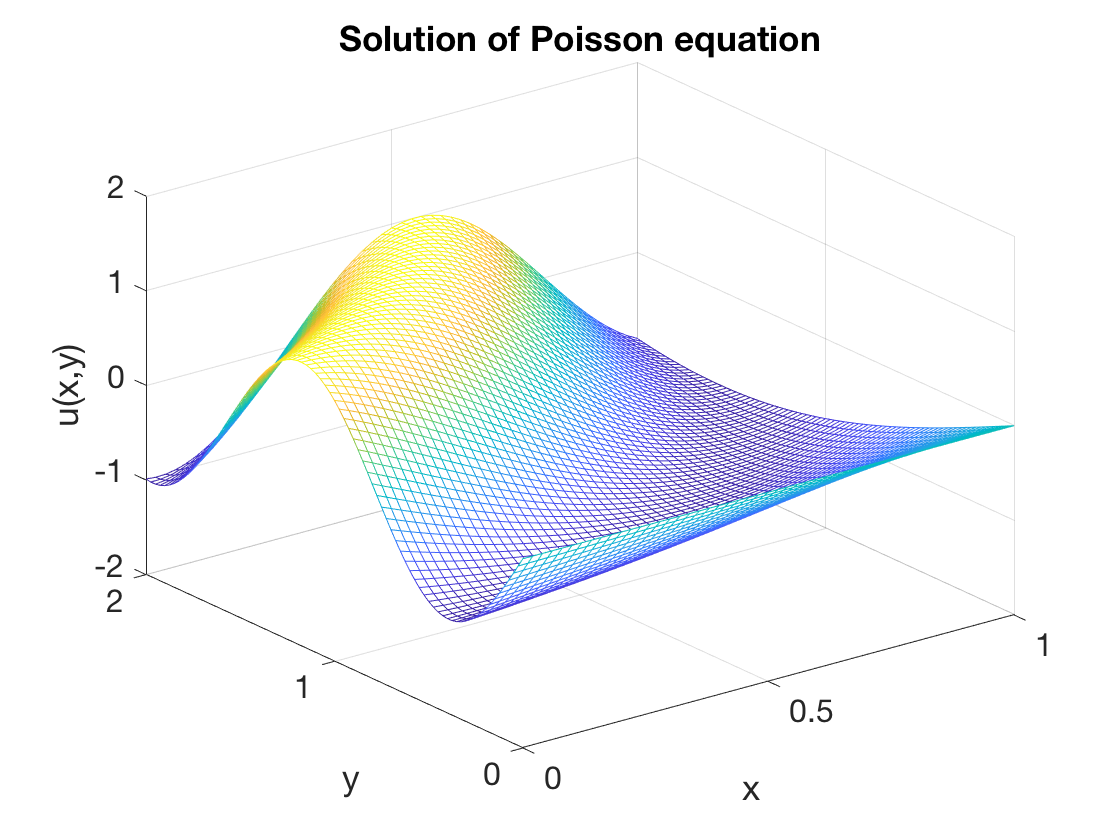

[U,X,Y] = poissonfd(f,g,50,xspan,80,yspan);
mesh(X,Y,U)
title('Solution of Poisson equation')     % ignore this line
xlabel('x'), ylabel('y'), zlabel('u(x,y)')    % ignore this line

The error is a surprisingly smooth function.

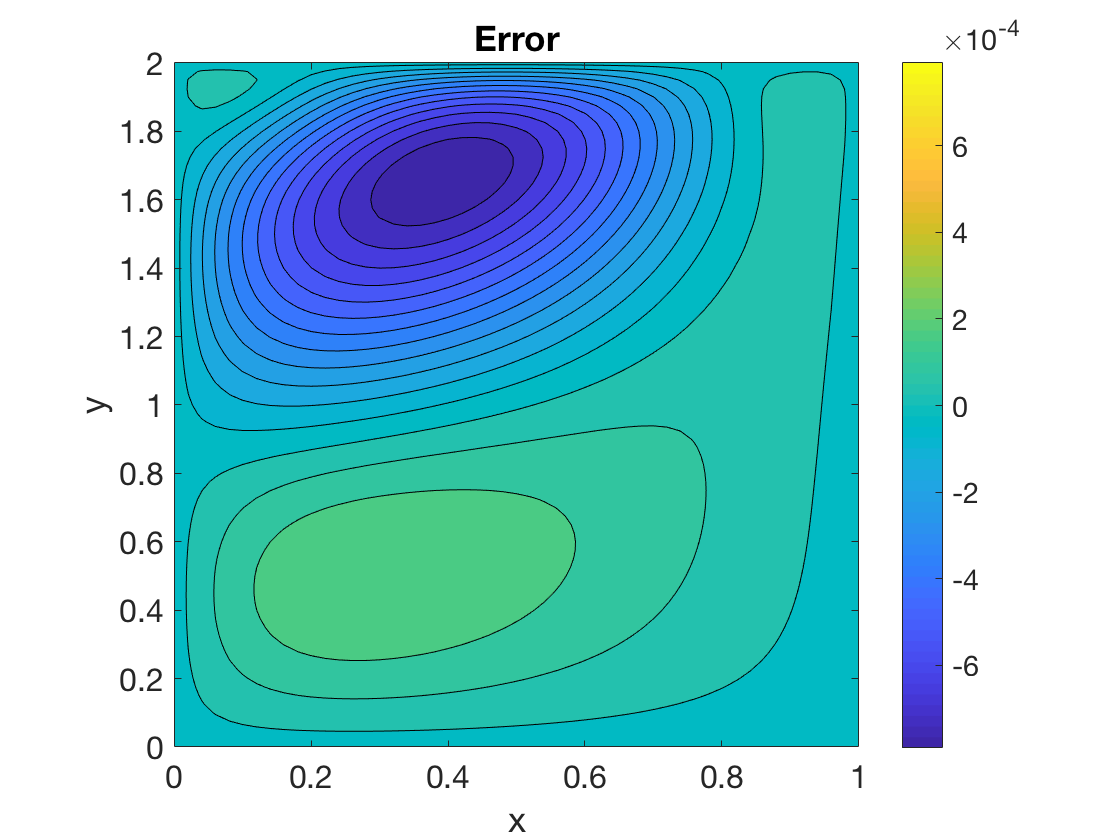

error = g(X,Y) - U;
contourf(X,Y,error,15)
axis equal, axis square     % ignore this line
M = max( max(error(:)),-min(error(:)) );    % ignore this line
caxis([-M M])    % ignore this line
shading flat, colorbar
title('Error')     % ignore this line
xlabel('x'), ylabel('y')   % ignore this line

Because $u$ is specified on the boundary, we should observe that the error is zero on the boundary---else we have done something incorrectly.